# 2.3.02. Разработка симуляторов для лабораторных работ в App Designer

**Практическое занятие**

Создайте приложение, наглядно демонстрирующее свободное падение тела.

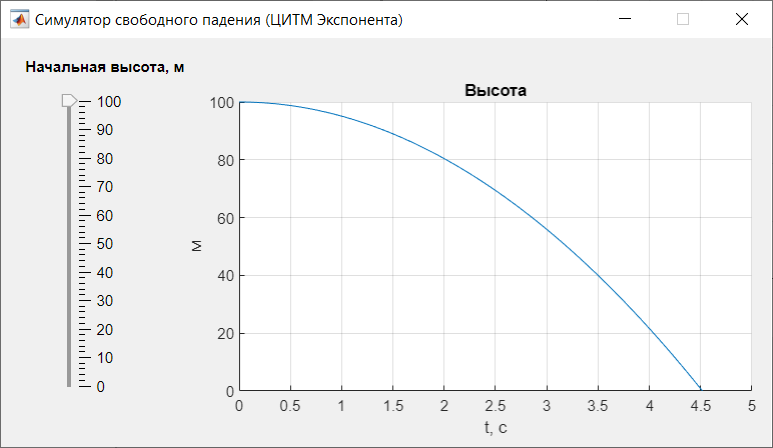

Создайте новое приложение в App Designer (*HOME -> New -> App*).

Сохраните его на диск с именем **lab02.mlapp**

Добавьте в графический интерфейс вашего приложения **слайдер** (Slider), затем:

- Переименуйте его в **app.Y0**

- Задайте диапазон от **0** до **100**

- Сделайте его **вертикальным**

- Подпишите как **Начальная высота**

- Добавьте слайдеру функцию обратного вызова (Callback) типа **ValueChangingFcn**

Добавьте в приложение **оси** (Axes), затем:

- Переименуйте их в **app.H**

- Подпишите как **Высота**

- Подпишите оси: **t,c** и **м**

- Включите **сетку**

На этом настройка графического интерфейса приложения окончена, переключитесь на редактироавние кода (Code View).

Создайте в приложении **функцию** (Private Function) со следующими параметрами:

- Имя: **calc**

- Входные аргументы: `app` и `y0`, где `y0` - начальная высота тела

- `Код`` функции:`

Как видите, задача функции - в зависимости от начальной высоты рассчитать изменение во времени высоты свободно падающего тела и отобразить результат на графике в осях `app.H`.

В Callback-функцию `Y0ValueChanging` добавьте вызов функции `calc` с передачей её текущего значения слайдера.

Запустите приложение кнопкой **Run** (F5) и убедитесь, что при перемещении слайдера изменяется график высоты.

Добавьте в приложение callback-функцию типа `StartupFcn` и впишите в неё вызов функции `calc` с передачей её текущего значения слайдера. Таким образом при запуске приложения график будет строиться автоматически.

**Приложение готово**. Убедитесь, что оно работает.

Для примера также посмотрите **симулятор математического маятника** [lab02_example.mlapp](matlab:open lab02_example)

lab02_example

*2018 © ЦИТМ Экспонента*